clear
clc
close all

% Define attractors of the network
T = [1 1; -1 -1; 1 -1]';

% Make meshgrid with set of initial states
x = -1:0.1:1;
y = -1:0.1:1;
[A,B] = meshgrid(x,y);
c=cat(2,A',B');
Ai=reshape(c,[],2)';

% Initialise network
net = newhop(T);

% Run network with set of initial states
Y = net({400}, {}, Ai);

% Find the set of final states
final_states = cell2mat(Y(1,400));
unique_states = unique(final_states','rows')

unique_states =     -1    -1
    -1     0
    -1     1
     0    -1
     0     0
     0     1
     1    -1
     1     0
     1     1


% Calculate average number of iterations until convergence
percent_converged = zeros(1,20);

for i=1:400
    num_converged = 0;
    Y = net({i}, {}, Ai);
    final_states = cell2mat(Y(1,i))';
    for j=1:length(final_states)
        is_converged = ismember(final_states(j,:),unique_states,'rows');
        num_converged = num_converged + is_converged;
    end
    percent_converged(i) = num_converged/length(final_states);
end

percent_converged;

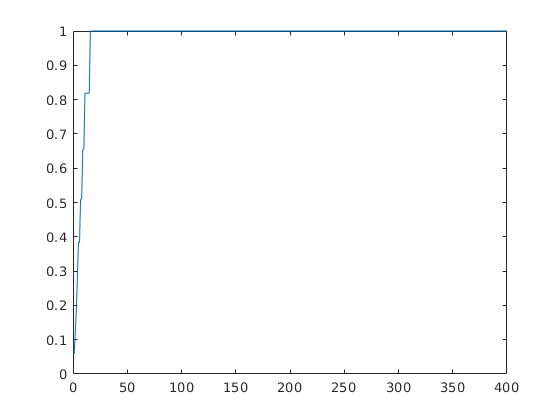

plot(percent_converged);

clear
clc
close all

% Define attractors of the network
T = [1 1 1; -1 -1 1; 1 -1 -1]';

% Make meshgrid with set of initial states
x = -1:0.1:1;
y = -1:0.1:1;
z = -1:0.1:1;
[ca, cb, cc] = ndgrid(x, y, z);
Ai = [ca(:), cb(:), cc(:)]';

% Initialise network
net = newhop(T);

% Run network with set of initial states
Y = net({400}, {}, Ai);

% Find the set of final states
final_states = cell2mat(Y(1,400))';
rounded_final_states = round(final_states, 4);

unique_states = unique(final_states,'rows')

unique_states =     -1    -1     1
     1    -1    -1
     1     1     1


rounded_unique_states = unique(rounded_final_states,'rows')

rounded_unique_states =     -1    -1     1
     1    -1    -1
     1     1     1


% Calculate average number of iterations until convergence
percent_converged = zeros(1,400);

for i=1:400
    num_converged = 0;
    Y = net({i}, {}, Ai);
    final_states = cell2mat(Y(1,i))';
    for j=1:length(final_states)
        is_converged = ismember(final_states(j,:),rounded_unique_states,'rows');
        num_converged = num_converged + is_converged;
    end
    percent_converged(i) = num_converged/length(final_states);
end

percent_converged

percent_converged =     0.0032    0.0181    0.0466    0.0910    0.1484    0.2106    0.2653    0.3288    0.4017    0.4846    0.4901    0.5782    0.5951    0.6832    0.6832    0.8001    0.8001    0.8001    0.8001    0.8001    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297    0.9297


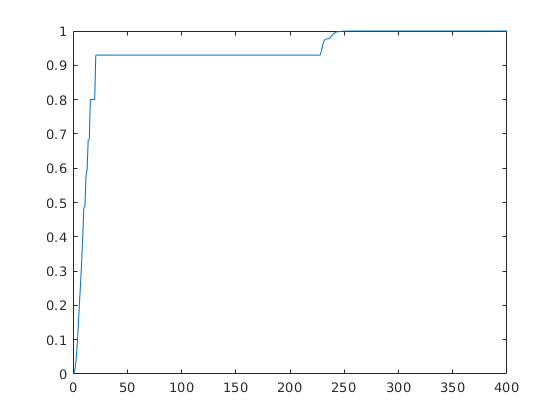

figure
x = 1:1:400;
plot(x,percent_converged)

ylim=([0 1.1]);
